# Second-order Boundary Value Problems

## bvp - Shooting method

The shooting method is based on converting the boundary-value problem into an equivalent initial-value problem by determining the missing  initial values that are consistent with the boundary values. 

A trial-and-error approach is implemented to develop a solution for the initial-value version that satisfies the given boundary conditions. 

### Ecuación diferencial lineal de segundo orden

Because the two conditions are given at different values of the independent variable, this is called a two-point boundary value problem.

y''- 4*y=0

y(0)=1, y(1)=3            Dirichlet boundary condition

A sequence of IVPs is produced, converging to the correct one. The sequence begins with an initial guess for the slope s=y'(a), provided to go along with the initial value y(a). The IVP that results from this initial slope is solved and compared with the boundary value yb. By trial and error, the initial slope is improved until the boundary value is matched. The boundary value problem is reduced to solving the equation 

ShootingF(s) = 0

to find the slope s=y'(a)

% y'' = 4*y
% y' = z
% z' = 4*y
% y(0)=1, y'(0)=¿?,  y(1)=3 
M = [0,1;4,0];
yzdot = @(t,yz) M*yz;
a=0;
b=1;
ya=1;
yb=3;
N=100;                  % número de puntos (índices:1 a N; n=N-1 intervalos)
h=(b-a)/(N-1);
% [ya;s] es la condicion inicial 
% y el target es la componente 1 de yz  y(1)=yb
target = 1;
g = @(s) QuarPar_shooting(yzdot, h, a, b, ya, s, target) - yb; %(f,h,x0,xf,t0,z0,target)
  
% Find starting values that bracket the root s; residual <0 y >0
r = g(-1)  
r = g(0)    
% Find the root s
[ydota,~] = R1_Biseccion(g,-1,0)   % valor de s=y'(a)            (=-0.4203)

Finally, the solution can be traced (by an IVP solver) as the solution to the initial value problem

yz0 = [ya; ydota];      % punto inicial (índice 1)

[t,yz] = TerPar_RK4(yzdot, a, yz0, h, b);%TerPar_RK4(f,t0,y0,h,tf)
plot(t,yz(1,:));
xlabel('t');
ylabel('y');
grid on;

El balance de calor de estado estacionario de una barra se representa como


$$\frac{{\mathrm{d}}^2 }{\mathrm{d}x^2 }T-0\ldotp 15\;T=0$$


Obtenga la solución T(x) para una barra de 10m con T(0)=240 y T(10)=150

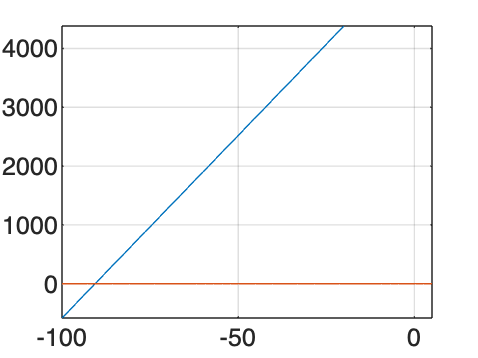

a=0;
ya=240;
b=10;
yb=150;
M = [0,1;0.15,0];
fun = @(t,yz) M*yz;
h =0.1;

target = 1;
g = @(z) QuarPar_shooting(fun, h, a, b, ya, z, target) - yb; %(f,h,x0,xf,t0,z0,target)
fplot(g, [-100, -20]);grid on; hold on; fplot(@(t)0); hold off;

guess1 = -90;
PrimerShoot = g(guess1)

PrimerShoot = 38.1421


za = R4_rfNewton(g,guess1) %Un punto considerablemente cercano

za = -90.6147


y0 = [ya;za];

[t,y] = TerPar_RK4(fun, a, y0, h, b);

y(1,end)

ans = 150.0000

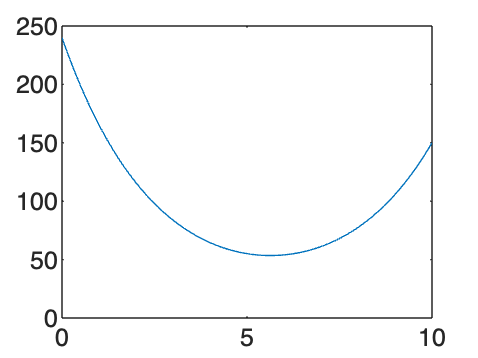

plot(t,y(1,:)), axis([0 10 0 250])

Resuelva $7\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }y-2\frac{\mathrm{d}}{\mathrm{d}t}y-y+t=0$ con las condiciones de frontera y(0) =5 y y(20)=8

a = 0;
b = 20;
ya = 5;
yb = 8;

vecB = @(t) [0;-t/7];
M = [0, 1;1/7,2/7];

fun = @(t, yz) M*yz + vecB(t)

fun = function_handle with value:
    @(t,yz)M*yz+vecB(t)


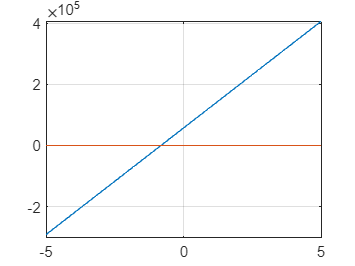


h =0.1;

target = 1;

g = @(z) QuarPar_shooting(fun, h, a, b, ya, z, target) - yb; %(f,h,x0,xf,t0,z0,target)

fplot(g);grid on; hold on; fplot(@(t)0); hold off;

guess1 = -0.81;
PrimerShoot = g(guess1)

PrimerShoot = 1.2937e+03


za = R4_rfNewton(g, guess1)

za = -0.8286


y0 = [ya, za];

[t,y] = TerPar_RK4(fun, a, y0, h, b);

y(1,end)

ans = 8.0000

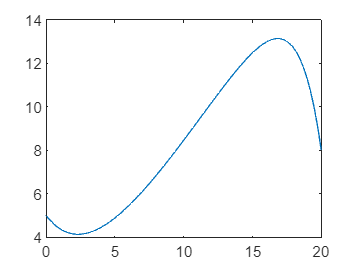

plot(t,y(1,:))

### Sistema de ecuaciones diferenciales de primer orden

For systems of ordinary differential equations, boundary value problems arise in many forms (boundary conditions).


$$y_1 \prime =\frac{4-2y_2 }{t^3 }$$



$$y_2 \prime =-e^{y_1 }$$



$$y_1 \left(1\right)=0,y_2 \left(2\right)=0$$


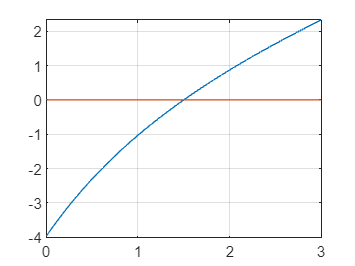

a = 1;
b = 2;
y1a = 0;
y2b = 0;
fun = @(t, y) [(4-2*y(2))/t^3;-exp(y(1))];


h =0.1;

target = 2;

g = @(z) QuarPar_shooting(fun, h, a, b, y1a, z, target) - y2b; %(f,h,x0,xf,t0,z0,target)

fplot(g, [0 3]); grid on; hold on; fplot(@(t)0, [0 3]); hold off;

guess1 = 1.5;
PrimerShoot = g(guess1)

PrimerShoot = -3.8778e-06


za = R4_rfNewton(g, guess1)

za = 1.5000

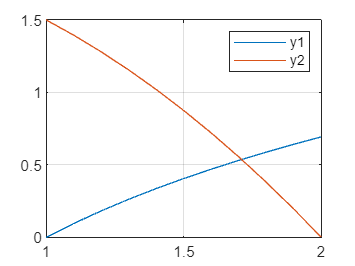


y0 = [y1a, za];

[t,y] = TerPar_RK4(fun, a, y0, h, b);

plot(t,y);legend("y1", "y2");grid on;

## Prueba 1: La barra caliente

hprim = 0.01; %constante de la función
Ta = 20; %Temperatura ambiente es parte de al función
f = @(t,y) [y(2); hprim*(y(1)-Ta)]; %Función de la barra caliente

T0 = 40; %Temperatura inicial o y(1(0))
TL = 200; %Temperatura final o y(1(end))
Li = 0; %Posición inicial o t(0)
Lf = 10; %Posición final 
h = 2; %Paso
target = 1; %grado de derivación del objetivo

%Si utilizamos la función auxiliar obtenemos solo el valor de la función
%con nuestra adivinanza
funAux=@(z)QuarPar_shooting(f,h,Li,Lf,T0,z,target); %QuarPar_shooting(f,h,x0,xf,t0,z0,target)

%La función g calcula la diferencia entre la adivinanza y el valor real,
%queremos que sea cero.
g = @(t) funAux(t) - TL;

%Esto para más o menos comprobar que el método para buscar z1 va a
%converger.
%Haremos tantas adivinanzas cuantas sea necesario para encontrar un valor
%cercano a cero. Si quedamos por debajo (negativo) aumentaremos el valor y
%viceversa. 
guess1 = 10;
PrimerShoot=g(guess1)

PrimerShoot = -31.6203

guess2 = 20;
SegundoShoot=g(guess2)

SegundoShoot = 85.8980

guess3 = 15;
TercerShoor=g(guess3)

TercerShoor = 27.1388

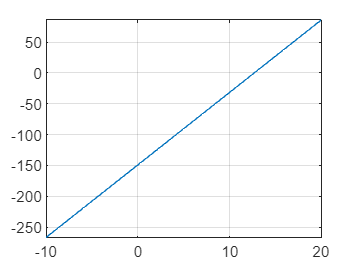


 
% [z1(1),i1(1)] = R1_Biseccion(g,-1,0) %Un punto arriba y otro abajo
% [z1(2),i1(2)] = R2_Interpolacion(g,-1,0) %Un punto arriba y otro abajo
% [z1(3),i1(3)] = R3_Secante(g,1,2) %Dos puntos arriba
fplot(g, [-10,20]);grid on;

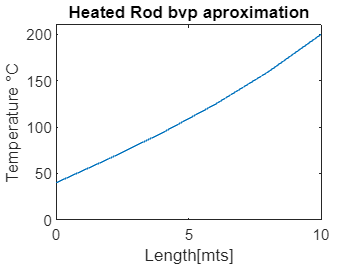

za = R4_rfNewton(g,guess3); %Un punto considerablemente cercano
%Elegimos un método, RfNewton utiliza solo un parámetro, cualquiera
%funciona.

y0=[T0;za]; %Concatenamos las condiciones iniciales ya conocidas con la z1 calculada. 


%Corremos el RK4 con la recién abtenida aproximación "y0 con z1" y
%graficamos el resultado"
[t1,y1]=TerPar_RK4(f,Li,y0,h,Lf);%TerPar_RK4(f,t0,y0,h,tf)

plot(t1,y1(1,:))
axis([0 10 0 210])
xlabel("Length[mts]")
ylabel("Temperature °C")
title("Heated Rod bvp aproximation")
hold off

## bvp - Finite Difference method

Replace the derivatives with the discrete versions and solve the resulting, simpler, algebraic equations.

### Ecuación diferencial lineal de segundo orden


$$\textrm{y''}-4y=0$$



$$y\left(0\right)=1,y\left(1\right)=3$$


Use the centered difference form of the second derivative accurate up to an error proportional to$h^2$.


$$\textrm{y''}\left(i\right)=\frac{y\left(i-1\right)-2y\left(i\right)+y\left(i+1\right)}{h^2 }$$


y''-4*y=0

y''(i) - 4y(i) = (y(i-1)-2y(i)+y(i+1))/h^2 - 4y(i) = 0

y(i-1)-2y(i)+y(i+1)-4*h^2*y(i) = 0

y(i-1)-(2+4*h^2)*y(i)+y(i+1)) = 0

y considerando y(1)=1 y y(N)=3 (boundary conditions)

1 -  (2+4*h^2)*y(2) + y(3)    = 0

y(2) - (2+4*h^2)*y(3) + y(4) = 0

y(3) - (2+4*h^2)*y(4) + y(5) = 0

   ...

y(N-2) - (2+4*h^2)*y(N-1)+3 = 0

finalmente (tenemos una matriz tridiagonal con N-2 variables: 2 a N-1)

-(2+4*h^2)*y(2) + y(3)                   = -1

y(2) - (2+4*h^2)*y(3) + y(4)           =  0

y(3) - (2+4*h^2)*y(4) + y(5)           =  0

   ...

 y(N-2) - (2+4*h^2)*y(N-1)             = -3

Since the nodes are numbered consecutively, and since each equation consists of a node (i) and its adjoining neighbors (i-1 and i+1), the resulting set of linear algebraic equations will be tridiagonal. As such, they can be solved with the efficient algorithms that are available for such systems. Further, inspection of the coefficients on the left-hand side indicates that the system of linear equations will also be diagonally dominant. Hence, convergent solutions can also be generated with iterative techniques like the Gauss-Seidel method.

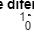

a=0;
b=1;
ya=1;
yb=3;
N=100; 
h=(b-a)/(N-1);

% w(i) = y(i+1)    matriz de puntos interiores
bv=zeros(N-2,1);    
bv(1) = -ya;   
bv(N-2) = -yb;
diagonal = -(2+4*h^2)*ones(N-2,1);
subdiagonal = ones(length(diagonal),1);
superdiagonal = subdiagonal;
w = QuarPar_Tridiag(subdiagonal,diagonal,superdiagonal,bv);

y=zeros(N,1);
y(1) = ya;
y(N) = yb;
y(2:N-1) = w;

t=a:h:b;
plot(t,y);
title('Método de diferencias finitas');
xlabel('t');
ylabel('y');
grid on;

El balance de calor de estado estacionario de una barra se representa como


$$\frac{{\mathrm{d}}^2 }{\mathrm{d}x^2 }T-0\ldotp 15\;T=0$$


Obtenga la solución T(x) para una barra de 10m con T(0)=240 y T(10)=150

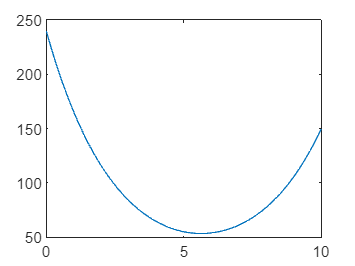

%function [t,y] = QuarPar_bvplineal2(g0,g1,g2,a,b,ya,yb,n)
a = 0;b = 10; ya = 240;yb = 150;n=100;
g0 = @(t) 0+0*t;
g1 = @(t) .15+0*t;
g2 = @(t) 0+0*t;
[t, y] = QuarPar_bvplineal2(g0,g1,g2,a,b,ya,yb,n);
plot(t,y)

Usando el método de diferencias finitas, resuelve el siguiente problema:


$$7\frac{d^2 }{\mathrm{d}t^2 }y-2\frac{d}{\textrm{dt}}y-y+t=0$$
         
$$y\left(0\right)=5\;,\;\;y\;\left(20\right)=8$$


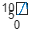

%function [t,y] = QuarPar_bvplineal2(g0,g1,g2,a,b,ya,yb,n)
a = 0;b = 20; ya = 5;yb = 8;n=100;
g0 = @(t) 0-t/7;
g1 = @(t) 1/7+0*t;
g2 = @(t) 2/7+0*t;
[t, y] = QuarPar_bvplineal2(g0,g1,g2,a,b,ya,yb,n);
plot(t,y)

## Function *bvp2ode*

Write the function *bvp2ode* that computes the numerical solution of the boundary value problem


$$\frac{d^2 }{\mathrm{d}t^2 }y=g_0 \left(t\right)+g_1 \left(t\right)y+g_2 \left(t\right)\frac{\mathrm{d}}{\mathrm{d}t}y$$


$y\left(t_0 \right)=y_0$  , $y\left(t_f \right)=y_f$

function [t, y] = bvp2ode(g0, g1, g2, tspan, bc, n)

where

    g0, g1, and g2 are function handlers. 

    t0 and tf are stored in the vector tspan =[t0 tf]

    y0 and yf are stored in the vector bc = [y0 yf].

    n is the number of interior points (there are n+2 points counting the borders)

    y is a column vector.

Use standard second order approximations for y' and y'' to construct a linear system of

equations for computing approximate values of the function y on the set of evenly spaced points.

Central finite differences:


$$y^{\prime \prime } \left(i\right)=\frac{y\left(i+1\right)-2y\left(i\right)+y\left(i-1\right)}{h^2 }$$



$$y^{\prime } \left(i\right)=\frac{y\left(i+1\right)-y\left(i-1\right)}{2h}$$
